**Exercise 1**

Try to approximate the value of the function $f(x) = e^{3x^2 + 4x}$ at $x = 0.1$using the first 4 terms of the Taylor series

clear; clc; close all;

syms x
f = exp(3*x^2 + 4*x);

taylorApprox = taylor(f, x, 0, "Order", 4); %Order 4
x0 = 0.1;

taylor4 = double(subs(taylorApprox, x, x0));
exact   = exp(3*x0^2 + 4*x0);
absErr  = abs(exact - taylor4);

disp(taylorApprox)

$$\frac{68\,x^{3}}{3}+11\,x^{2}+4\,x+1$$

fprintf("Approx: %.12f\nExact : %.12f\nAbsErr: %.12e\n", taylor4, exact, absErr);

Approx: 1.532666666667
Exact : 1.537257523548
AbsErr: 4.590856881615e-03


**Exercise 2**

Make a function that estimates the derivative of a function based on a finite difference approximation.

You may use a `switch-case` structure to handle the different methods, e.g.:

$f'(x_j) \approx \frac{f(x_j + h) - f(x_j)}{h}$.

Make the function robust, such that it handles $x$ as both a single value and vector.

Test it with $f(x) = \sin (x)$ evaluated at $n = 21$ positions and thus $h = \pi / 10$.

Plot the derivatives and the error using `subplot and discuss the characteristics of the error.`

clear; clc; close all;

f  = @(x) sin(x);
df = @(x) cos(x);

n = 21;
h = pi/10;
x = (0:n-1) * h;

% Approximations
dF = fdiff(f, x, h, "forward");
dB = fdiff(f, x, h, "backward");
dC = fdiff(f, x, h, "central");

% Exact + errors
dExact = df(x);
eF = dF - dExact;
eB = dB - dExact;
eC = dC - dExact;

% Plots
figure;

subplot(2,1,1)
plot(x, dExact); hold on;
plot(x, dF);
plot(x, dB);
plot(x, dC);
grid on;
xlabel("x"); ylabel("d/dx");
title("Derivative of sin(x): exact vs finite differences");
legend("Exact: cos(x)","Forward","Backward","Central","Location","best");

subplot(2,1,2)
plot(x, eF); hold on;
plot(x, eB);
plot(x, eC);
yline(0,"--");
grid on;
xlabel("x"); ylabel("Error (approx - exact)");
title("Error of finite-difference methods");
legend("Forward error","Backward error","Central error","Location","best");

% summary
fprintf("h = %.6f\n", h);

h = 0.314159


fprintf("Max |error| forward : %.3e\n", max(abs(eF)));

Max |error| forward : 1.558e-01


fprintf("Max |error| backward: %.3e\n", max(abs(eB)));

Max |error| backward: 1.558e-01


fprintf("Max |error| central : %.3e\n", max(abs(eC)));

Max |error| central : 1.637e-02


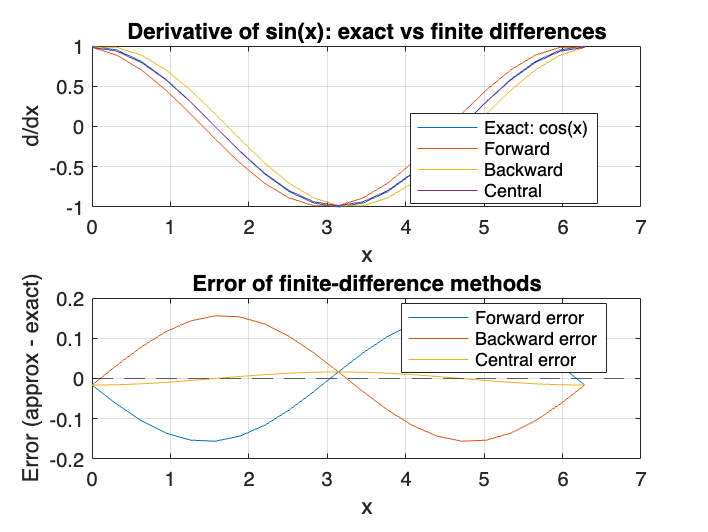


hold off;


function dfdx = fdiff(f, x, h, method)
    % method: "forward", "backward", "central" (default: "central")

    if nargin < 4 || isempty(method)
        method = "central";
    end
    if ~isa(f, "function_handle")
        error("f must be a function handle");
    end
    if ~isscalar(h) || h <= 0
        error("h must be a positive scalar");
    end

    % preserve shape of input vector but work as column internally
    x_in = x;
    x = x(:);

    switch lower(method)
        case {"forward","fwd"}
            dfdx = (f(x + h) - f(x)) / h;

        case {"backward","bwd"}
            dfdx = (f(x) - f(x - h)) / h;

        case {"central","ctr"}
            dfdx = (f(x + h) - f(x - h)) / (2*h);

        otherwise
            error("Unknown method '%s'. Use 'forward', 'backward', or 'central'", method);
    end

    dfdx = reshape(dfdx, size(x_in));
end